clear
N_observation = 32;
n_subcarrier = 256;
freq_carrier = 3e9;
freq_IF = 2e7;
freq_shift = 500;
lambda = 3e8 / freq_carrier;
T_symbol = 1e-4;
N_sample = 8192; %8192
symbols_per_frame = 2;
pri = T_symbol*symbols_per_frame;
prf = 1 / pri;
freq_sampling = N_sample / T_symbol;
range_per_sampling_period = 3e8 * (1/freq_sampling) / 2;
rcs = 1;
Gt = 2936;
Gr = 2936;
Bn = (1/T_symbol)/symbols_per_frame;                        % BW post doppler
t = (linspace(0, T_symbol, n_subcarrier))';                 %symbol time
t2 = (linspace(0, T_symbol, N_sample))';                    %symbol time interpolated
pri_t = (linspace(0, pri, N_sample*symbols_per_frame))';    %pri time

## Wave Generator

%golay coding
golay_reg = golay(n_subcarrier);
golay_symbol_index = 1;
golay_code_value = golay_reg(golay_symbol_index, :);

%phase shifting
% alpha = deg2rad(90);
% deltat = -alpha ./ (2*pi*f);
% phase_shift = exp(1j * 2 * pi * f .* deltat);
% signal = golay_code_value .* phase_shift;

%ifft
iq_signal = ifft(golay_code_value, n_subcarrier)';

if N_sample > n_subcarrier
    a = 1:1:n_subcarrier;
    b = linspace(1, n_subcarrier, N_sample);
    iq_signal = interp1(a,iq_signal,b)';
end

% %offset-freq and IF Freq signal 
carrier = exp(-1i*2*pi*(freq_IF)*t2);
freq_shift = exp(-1i*2*pi*(freq_shift)*t2);
iq_signal = iq_signal .* carrier;

%IQ modulator
tx_signal = (real(iq_signal) + imag(iq_signal));
zero_padded_signal = [tx_signal; zeros((N_sample*(symbols_per_frame-1)), 1)];

## Antenna & Channel Initialization

% waveform = phased.RectangularWaveform('SampleRate',freq_sampling,...
%     'PulseWidth',pri,'OutputFormat','Pulses',...
%     'N_observation',1,'PRF',prf); %1ms
target = phased.RadarTarget('Model','Nonfluctuating',...
    'MeanRCS',1,'OperatingFrequency',freq_carrier);
targetpos = phased.Platform('InitialPosition',[11000; 0; 0],...
    'Velocity',[70; 0; 0]);
antenna = phased.IsotropicAntennaElement(...
    'FrequencyRange',[5e8 5e9]);
transmitter = phased.Transmitter('PeakPower',5e3,'Gain',34,...
'InUseOutputPort',true);
transpos = phased.Platform('InitialPosition',[0;0;0],...
    'Velocity',[0;0;0]);
radiator = phased.Radiator('OperatingFrequency',freq_carrier,'Sensor',antenna);
collector = phased.Collector('OperatingFrequency',freq_carrier,'Sensor',antenna);
channel = phased.FreeSpace('SampleRate',freq_sampling,...
    'OperatingFrequency',freq_carrier,'TwoWayPropagation',false);
receiver = phased.ReceiverPreamp('Gain',100,'LossFactor',0,...
    'SampleRate',freq_sampling,'NoiseFigure',5,...
    'EnableInputPort',false,'SeedSource','Property','Seed',1e3);

## Antenna and Channel Modelling

sig = zero_padded_signal; %Gain to make the Tx Power 161.2
transpos = transpos.InitialPosition; % get transmitter position
rxsig = zeros(length(sig),N_observation);

for i = 1:N_observation
    % update target position
    [tgtpos,tgtvel] = targetpos(pri);
    [tgtrng,tgtang] = rangeangle(tgtpos,transpos);
    [txsig,txstatus] = transmitter(sig); % transmit waveform
    txsig1 = radiator(txsig,tgtang); % radiate waveform toward target
    txsig2 = channel(txsig1,transpos,tgtpos,[0;0;0],tgtvel); % propagate waveform to target
    txsig3 = target(txsig2); % reflect the signal
    % propagate waveform from the target to the transmiter
    txsig4 = channel(txsig3,tgtpos,transpos,tgtvel,[0;0;0]);
    txsig5 = collector(txsig4,tgtang); % collect signal
    rxsig(:,i) = receiver(txsig5); % receive the signal
end

rx_signal = real(rxsig) + imag(rxsig);

rx_signal_1 = rx_signal(:,1);
rx_signal_2 = rx_signal(:,2);
rx_signal_3 = rx_signal(:,3);
rx_signal_4 = rx_signal(:,4);
rx_signal_5 = rx_signal(:,5);
rx_signal_6 = rx_signal(:,6);
rx_signal_7 = rx_signal(:,7);
rx_signal_8 = rx_signal(:,8);
rx_signal_9 = rx_signal(:,9);
rx_signal_10 = rx_signal(:,10);

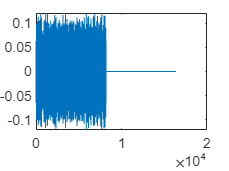

plot((sig))

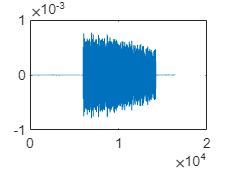

plot(rx_signal_1)

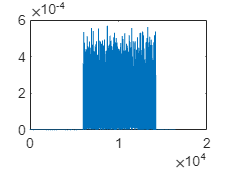

plot(abs(rxsig(:,1)))

[c,lags] = xcorr(rx_signal_1, sig);

%range processing
size_lags =  size(lags, 2);
lags_abs = lags(1, round(size_lags/2):size_lags);
c_abs = (c(round(size_lags/2):size_lags, 1));

rxy = c_abs;
tau = lags_abs * T_symbol / max(lags_abs);
lag_of_max_c = lags_abs(c_abs == max(c_abs))

lag_of_max_c = 6018


lag_delay_time = (1/freq_sampling) * lag_of_max_c;
range_target = 3e8 * lag_delay_time / 2

range_target = 1.1019e+04

yy = conv(rx_signal_1, flipud((sig)));

size_yy =  size(yy, 1);
yy_idxes = 1:round(size_yy/2)

yy_idxes =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


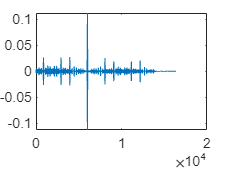

yy_abs = (yy(round(size_yy/2):size_yy,1));

plot(yy_abs)

[yymax, lag_of_max_yy] = max(yy_abs)

yymax = 0.1121

lag_of_max_yy = 6019

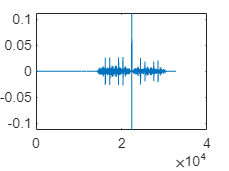

plot(c)

kk = rx_signal(lag_of_max_yy,:).';

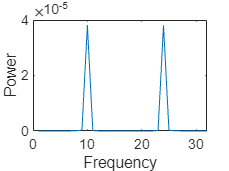

n = 32;
y = fft(kk, n);
% y = fftshift(y);         
f = (0:n-1)*(prf/n); 
% f = (-n/2:n/2-1)*(prf/n);     
power = abs(y).^2;  
absolute = (real(y).^2) + (imag(y).^2);
plot(absolute)
xlabel('Frequency')
ylabel('Power')


[Y_fft,I_fft] = max(absolute);
f(I_fft)

ans = 1.4062e+03

dop2speed(f(I_fft)/2,lambda)

ans = 70.3125

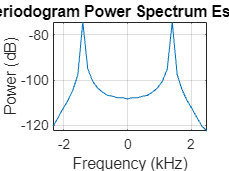

periodogram(rx_signal(lag_of_max_yy,:).',[],32,prf,'power','centered')

[Pxx,F] = periodogram(rxsig(lag_of_max_c+3,:).',[],32,prf,'power','centered');
[Y,I] = max(Pxx);
F(I)

ans = -1.4062e+03

dop2speed(F(I)/2,lambda)

ans = -70.3125